clear all

load Car.mat
Y = [r;theta];

q1 = 1;
q2 = 1;
DT = 0.1;
Q = [[q1/3*DT^3 0 q1/2*DT^2 0];[0 q2/3*DT^3 0 q2/2*DT^2];
    [q1/2*DT^2 0 q1*DT 0];[0 q2/2*DT^2 0 q2*DT]];
Q

Q =     0.0003         0    0.0050         0
         0    0.0003         0    0.0050
    0.0050         0    0.1000         0
         0    0.0050         0    0.1000


A = eye(4);
A(1,3) = DT;
A(2,4) = DT;

%because range and angle are conditionally independent given positions. We
%can compute both at same time using one R.
R = diag([0.5^2,0.1^2]);
R_radius = 0.5^2;
R_theta = 0.1^2;
m0 = [0;0;0;0];
P0 = 100*eye(4);

%taken from sol07.mlx
% Filter
nk = 100;
M=zeros(2,nk);

m=m0; P=P0;
M1s=zeros(2,nk);
Mf=zeros(4,nk); Pf=zeros(4,4,nk);
for k=1:nk
    [m,P]=gf_predict(m,P,@task4_f,Q,@GaussApproxUKF);
    if all(~isnan(Y(:,k)))
        [m,P]=gf_update(m,P,Y(:,k),@task4_h,R,@GaussApproxUKF);
    end
    M(:,k)=m(1:2);
    Mf(:,k)=m; Pf(:,:,k)=P;
end

%for some reason algorithm estimates x and y in order [y;x]. I was confused
%for this for very long time.
rmse=sqrt(mean(sum(([y;x]-M(1:2,:)).^2,1)));
disp(['RMS error for UKF is ' num2str(rmse)])

RMS error for UKF is 1.5705


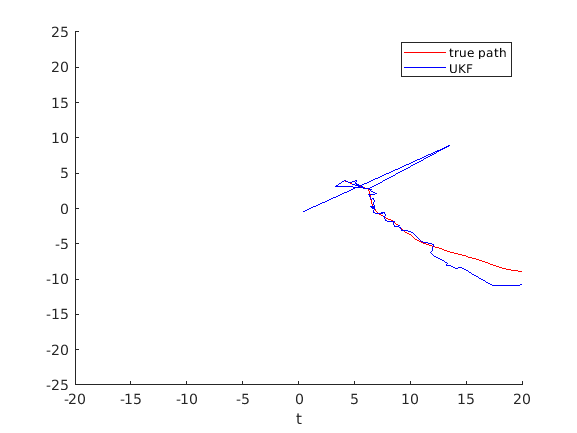


% Plot the paths

plot(x,y,'r-',M(2,:),M(1,:),'b-')
axis([-20 20 -25 25]), box off,  xlabel('t')
legend('true path','UKF') 


%smoothing,code taken from sol09.mlx
M1s(:,end)=m(1:2);
for k=nk-1:-1:1  % backward sweep (smoother)
    [mp,Pp,Dk]=GaussApproxUKF(Mf(:,k),Pf(:,:,k),@task4_f,Q); %CHANGED
    Gk=Dk/Pp;
    m=Mf(:,k)+Gk*(m-mp);
    P=Pf(:,:,k)+Gk*(P-Pp)*Gk';
    M1s(:,k)=m(1:2);
end


rmse=sqrt(mean(sum(([y;x]-M1s(1:2,:)).^2,1)));
disp(['RMS error for Smoothed UKF is ' num2str(rmse)])

RMS error for Smoothed UKF is 0.2842


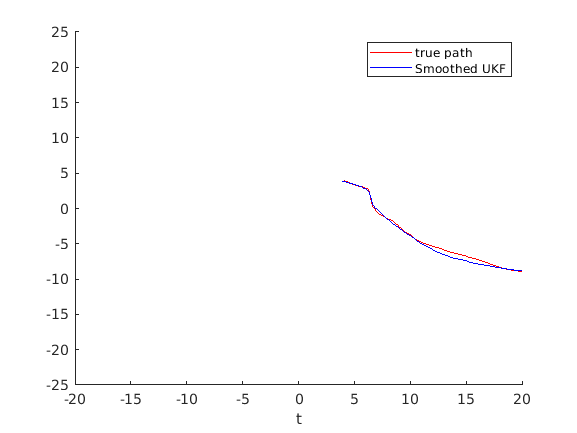


% Plot the paths

plot(x,y,'r-',M1s(2,:),M1s(1,:),'b-')
axis([-20 20 -25 25]), box off,  xlabel('t')
legend('true path','Smoothed UKF') 

Part b

%taken from pendulum_demo_PF.m
% Particle filter
nk = 100;
N = 2000;
m0 = [0;0;0;0];
P0 = 100*eye(4);
xx=mvnrnd(repmat(m0,1,N)',P0)';
xpf=zeros(length(m0),N,nk+1); 
xpf(:,:,1)=xx;
for k=1:nk
    xx=mvnrnd(task4_f(xx)',Q)';
    if all(~isnan(Y(1,k))) %CHANGED, all y values must be zero
        
        w=mvnpdf(Y(:,k)',(task4_h(xx))',R)'; % CHANGED
        w=w/sum(w);
        xx=xx(:,resamp(w));
    end
    xpf(:,:,k+1)=xx;
    M(1,k)=mean(xx(1,:));
    M(2,k)=mean(xx(2,:));
end


rmse=sqrt(mean(sum(([y;x]-M(1:2,:)).^2,1)));
disp(['RMS error for PF  is ',num2str(rmse)])

RMS error for PF  is 1.1118


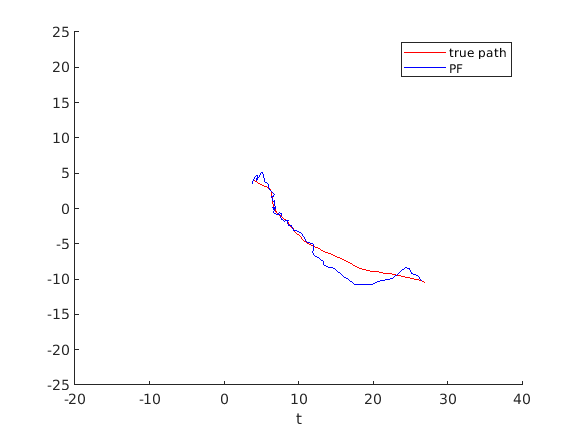


plot(x,y,'r-',M(2,:),M(1,:),'b-')
axis([-20 40 -25 25]), box off,  xlabel('t')
legend('true path','PF') 


% Backward-simulation particle smoother
nbs = 5;
xs=xpf(:,randi(N,1,nbs),nk+1);
for k=nk:-1:1
    for j=1:nbs
        w=mvnpdf(repmat(xs(:,j),1,N)',task4_f(xpf(:,:,k))',Q)'; %CHANGED
        w=w/sum(w);
        [~,J]=histc(rand,[0;cumsum(w(:))]); % a sample from 1:N
        xs(:,j)=xpf(:,J,k);
    end
    M(3,k)=mean(xs(1,:),2);
    M(4,k)=mean(xs(2,:),2);
    
end
rmse=sqrt(mean(sum(([y;x]-M(3:4,:)).^2,1)));
disp(['RMS error for PS  is ',num2str(rmse)])

RMS error for PS  is 0.69782


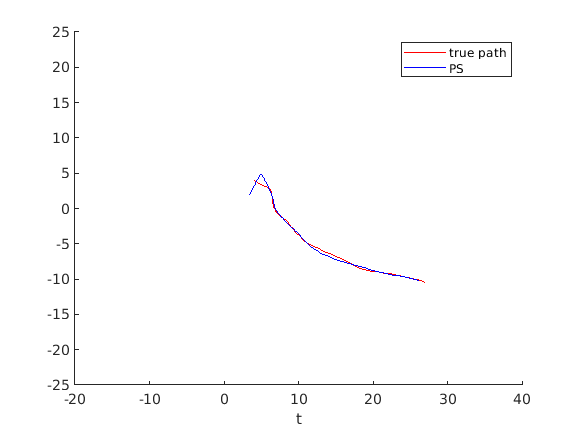


plot(x,y,'r-',M(4,:),M(3,:),'b-')
axis([-20 40 -25 25]), box off,  xlabel('t')
legend('true path','PS')

Functions

function hval=task4_h(x)
%x(1) = x
%x(2) = y

%radius
hval1 = sqrt(x(1,:).^2 + x(2,:).^2);

%angle
hval2= atan2(x(1,:),x(2,:));
hval = [hval1;hval2];
end

function fval=task4_f(x)
DT = 0.1;
A = eye(4);
A(1,3) = DT;
A(2,4) = DT;
fval = A*x;
end

%predict and update functions taken from sol07.mlx
function [m,P]=gf_predict(m,P,f,Q,GaussApprox)
[m,P]=GaussApprox(m,P,f,Q);
end

function [m,P]=gf_update(m,P,y,h,R,GaussApprox)
if ~isnan(y)
    [mu,S,C]=GaussApprox(m,P,h,R);
    K=C/S;
    P=P-K*S*K';
    m=m+K*(y-mu);
end
end

function [mu,S,C,X]=GaussApproxUKF(m,P,g,E)
%taken from exercise 7 model solutions
nx=length(m);
alpha=1; beta=0; kappa=max(3-nx,1);
lambda=alpha^2*(nx+kappa)-nx;
WM=repmat(0.5/(nx+lambda),2*nx+1,1);
WM(1)=lambda/(nx+lambda);
WC=WM; WC(1)=lambda/(nx+lambda)+1-alpha^2+beta;
A=chol(P,'lower');   % use schol if P is singular
X=[m repmat(m,1,2*nx)+sqrt(lambda+nx)*[A -A]];
Y=g(X); ny=size(Y,1);
mu=zeros(ny,1); S=E; C=zeros(nx,ny);
for i=1:length(WM)
    mu=mu+WM(i)*Y(:,i);
end
for i=1:length(WC)
    S=S+WC(i)*(Y(:,i)- mu)*(Y(:,i) - mu)';
    C=C+WC(i)*(X(:,i)-m)*(Y(:,i) - mu)';
end
end

function J=resamp(W)
u=rand(length(W),1);
[~,J]=histc(u,[0;cumsum(W(:))]);
end